# Control of Electric Drives and Power Converters

## Assignment 1.

#### Tasks 1 & 2.

Determining the number of pole pairs:

n = 1436; % Nominal motor speed [rpm]
f = 50; % Frequency [Hz]
n_p = floor(60*f/n);

From the calculation we can see that


$$n_p =\frac{60*50\;\textrm{Hz}}{1436\;\frac{r}{\min }}=2$$


For the first task of the assignment, we were asked to derive the equations for the stator current $i_s^s$ and the rotor current $i_R^s$ as a function of stator flux $\psi_s^s$ and rotor flux $\psi_R^s$ in stator coordinates. This was achieved by inserting gain and summation blocks in the "Flux equations" function bloc, as seen in the Fig. 1

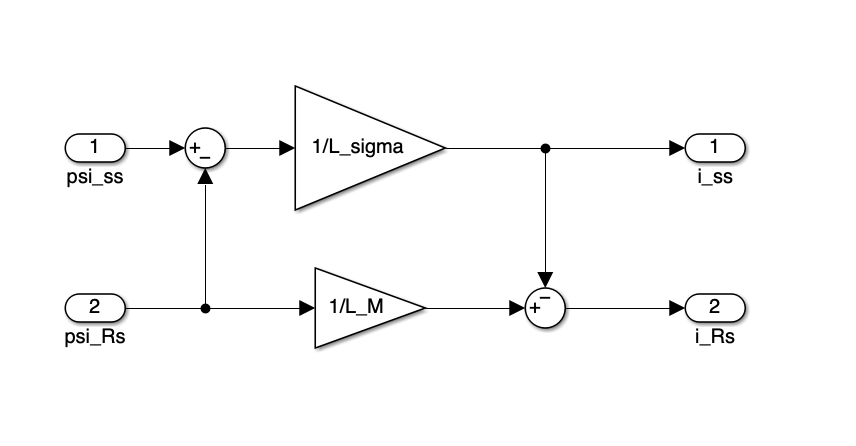 

*Figure 1. Flux equations fuction block*

After this, the equation for electromagnetic torque was formed inside the "Electromagnetic torque" function block, as seen in the Fig. 2.

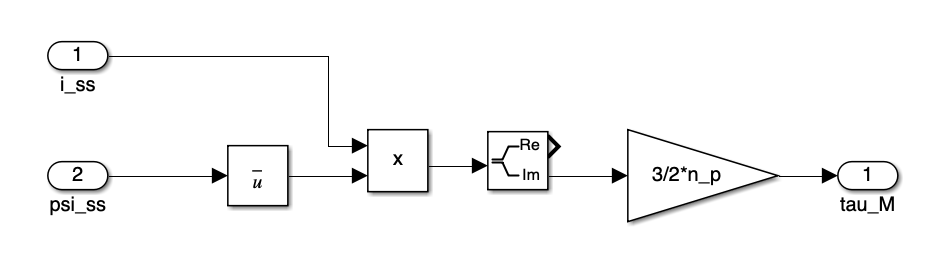

*Figure 2. Electromagnetic torque control block*

The nominal torque $\tau_N =\frac{P_N }{\omega_N }=\frac{P_N }{n_N \frac{2\pi }{60s}}=\frac{2200W}{1436\frac{1}{\min }\frac{2\pi }{60s}}\approx 14\ldotp 63\textrm{Nm}$

The nominal peak to peak line to neutral voltage $v_{p-p,\textrm{pn}} =\sqrt{2}\;\frac{\;400V}{\sqrt{3}}\approx 326\ldotp 6V$

#### Task 3.

The missing part of the algorithm was completed by inserting the equation for $u_s^s$, which is


$$u_s^s \left(k\right)=\psi_{s,\textrm{ref}} *\omega_{s,\textrm{ref}} \left(k\right)*e^{j\theta_s \left(k\right)\;\;}$$


Running the intialization script:

init_vhz;

Simulating the system:

sim("vhz.slx");

Plotting the result:

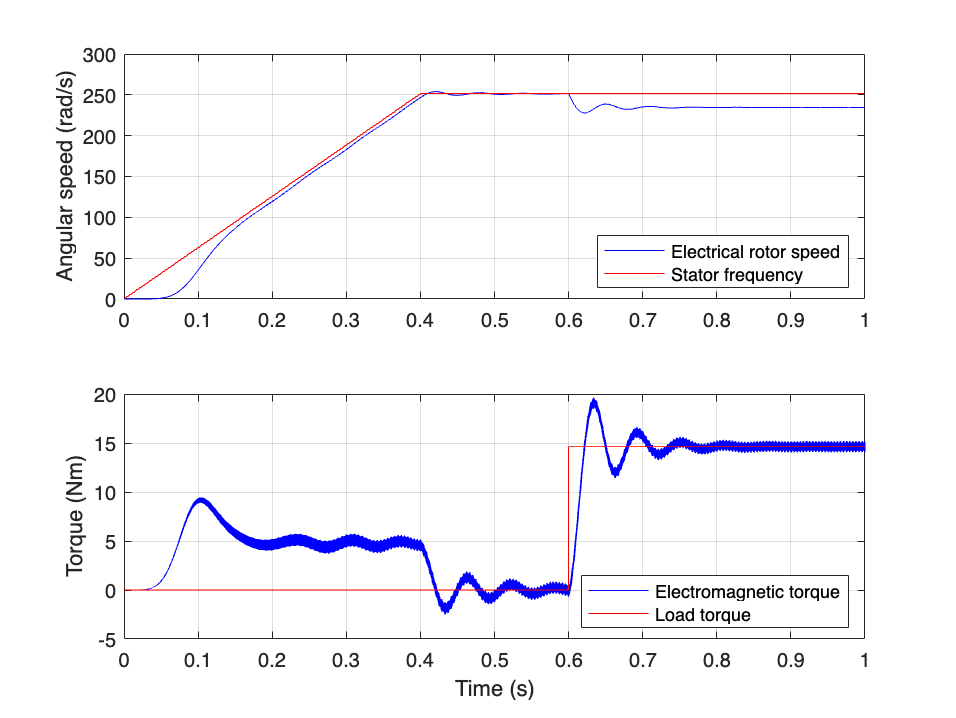

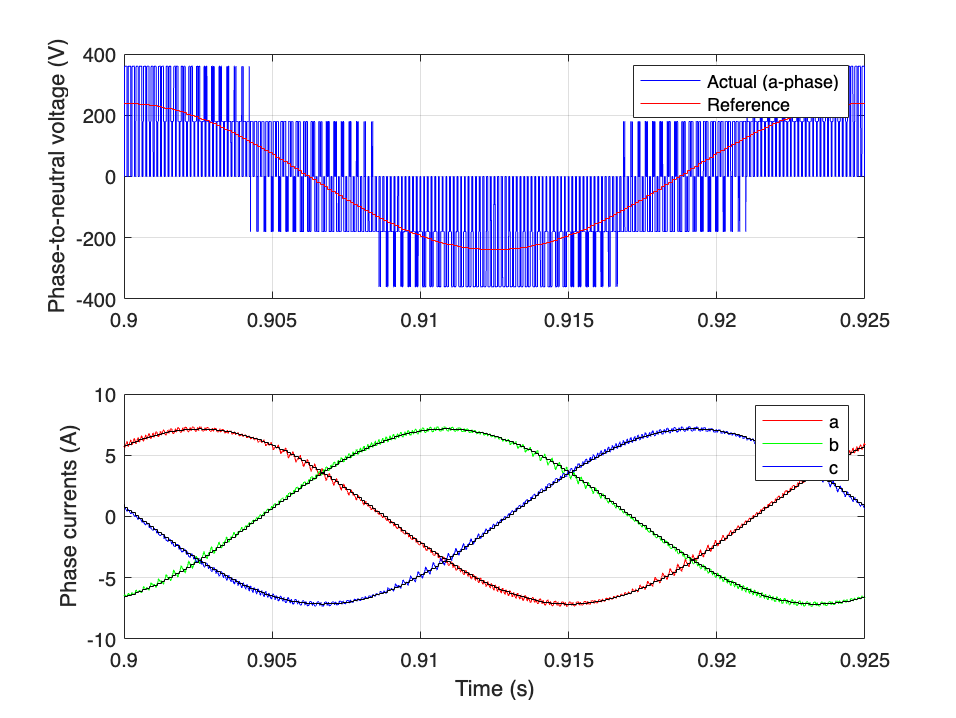

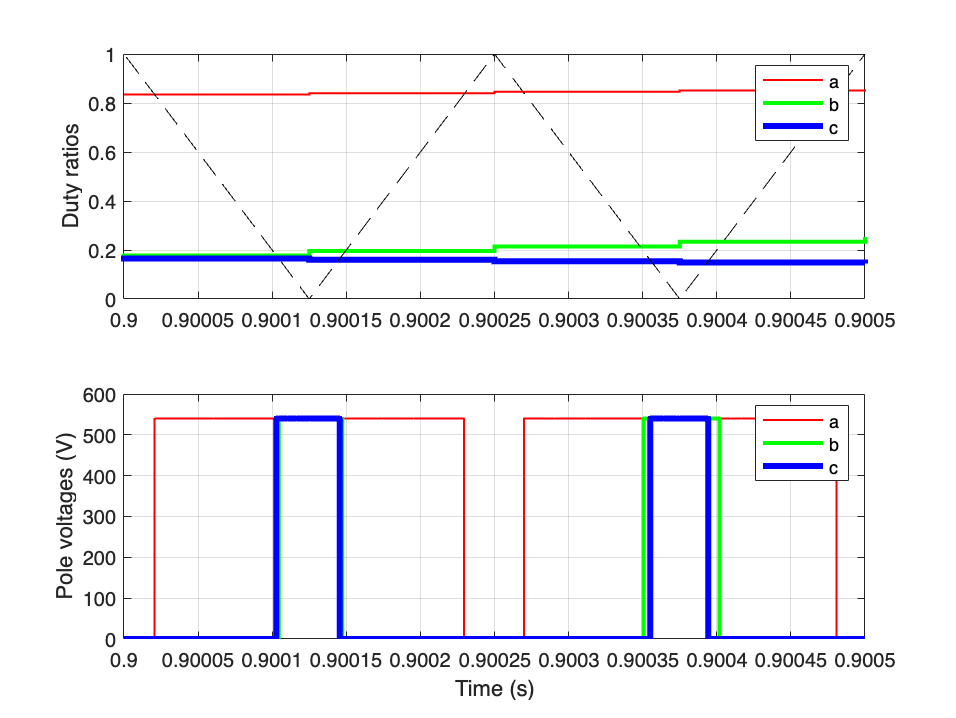

fig_vhz;

The figures seem to match pretty well with the one's given in the assignment for comparison.

#### Task 4.

The stator voltage for these calculations was approximated by using the equation


$$u_s =\omega_{s,\textrm{ref}} \psi_{s,\textrm{ref}} =2\pi 40\;\frac{\textrm{rad}}{s}*0\ldotp 95\;\textrm{Vs}=238\ldotp 76\;V$$


The stator impedance in steady state is


$$Z_s =R_s +j\omega \left(L_{\sigma } +L_M \right)=3\ldotp 7\Omega +\textrm{j80}\pi \frac{\textrm{rad}}{s}\;\left(21\;\textrm{mH}+224\;\textrm{mH}\right)=\left(3\ldotp 7+\textrm{j61}\ldotp 57\right)\Omega$$


And hence, the peak stator current is


$$i_s =\frac{u_s }{{|Z}_s |}=3\ldotp 87\;A$$


Plotting the calculated stator current value against the simulated one can be seen in Fig. 3. For the simulation, the load torque step final value was set to 0, but the rate limiter of the speed reference was kept untouched, which explains the peaks in stator current before reaching steady state.

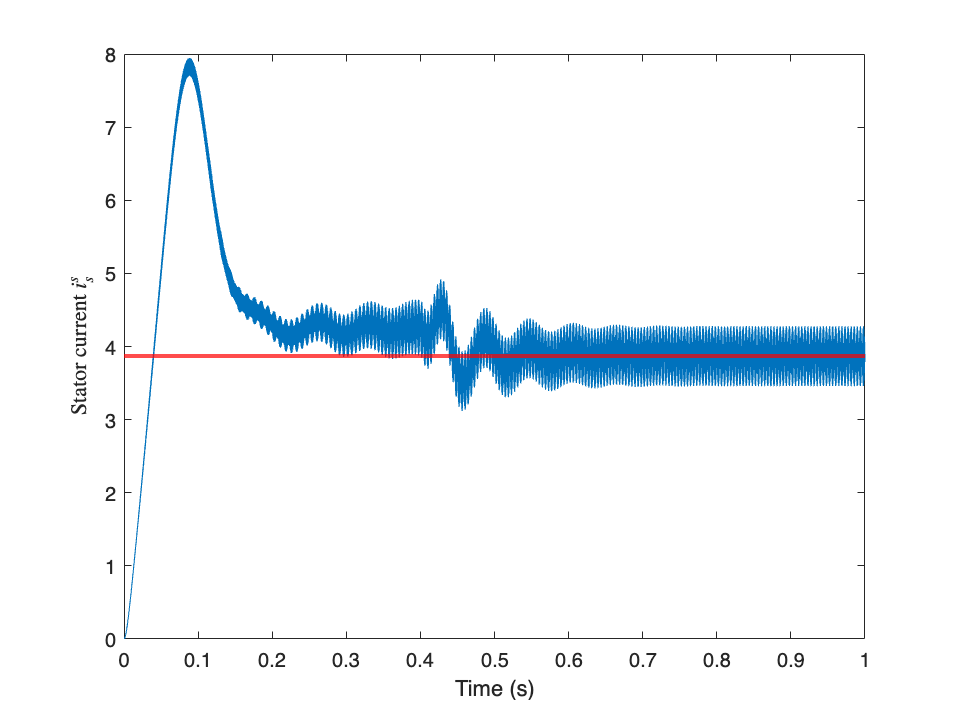

T_L = 0; % load torque
sim("vhz.slx");
task_4_script;

*Figure 3. Simulated and calculated stator current*

As can be seen from the figure the calculated stator current value matches the simulated one quite well in steady state operating area. 

#### Task 5.

To decrease $f_{\mathrm{sw}}$ to 2kHz we calculated sampling period $T_S$ to correspond to the lower switching frequency.

f_sw = 2e3; % switching frequency
T_s = 1/(2*f_sw); %sampling period
T_L = 14.63; % returning the load torque back to its nominal value

Simulating the model again with new parameters and also running the plotting script.

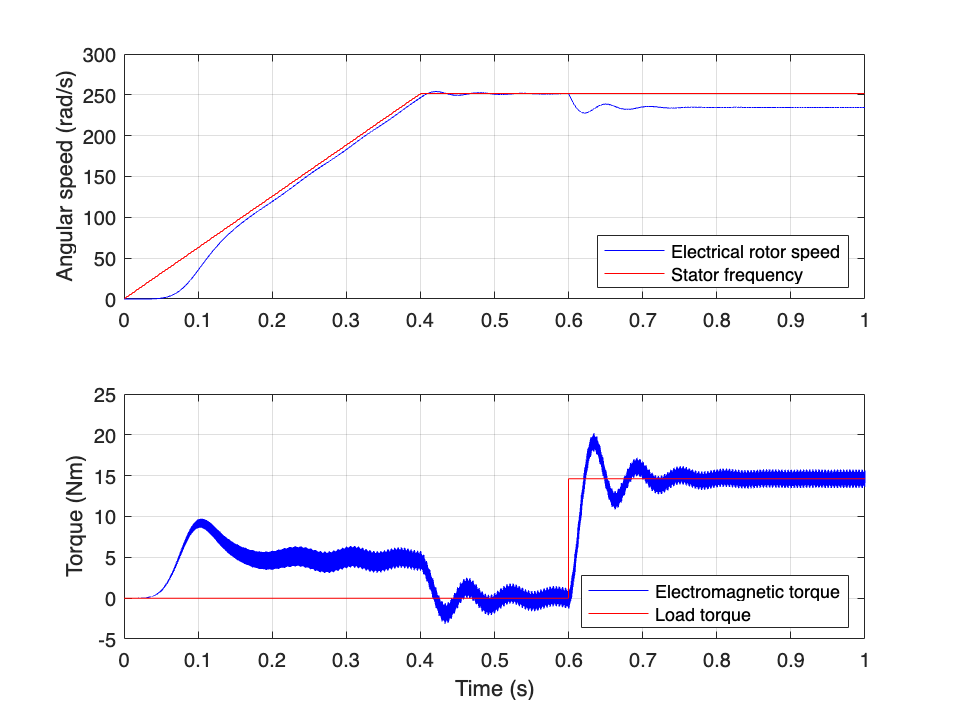

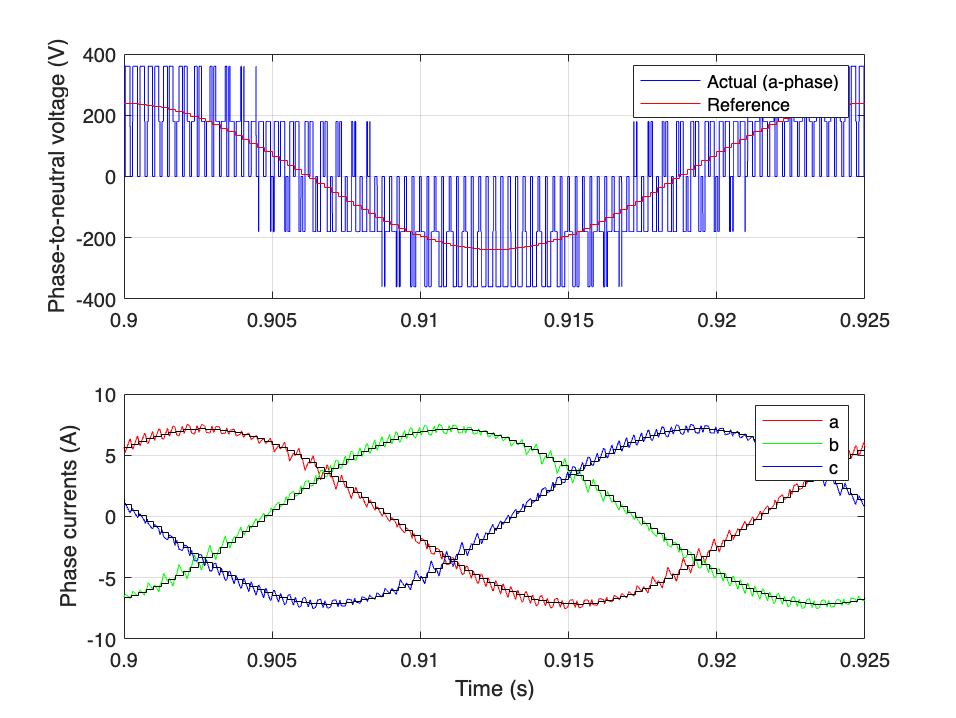

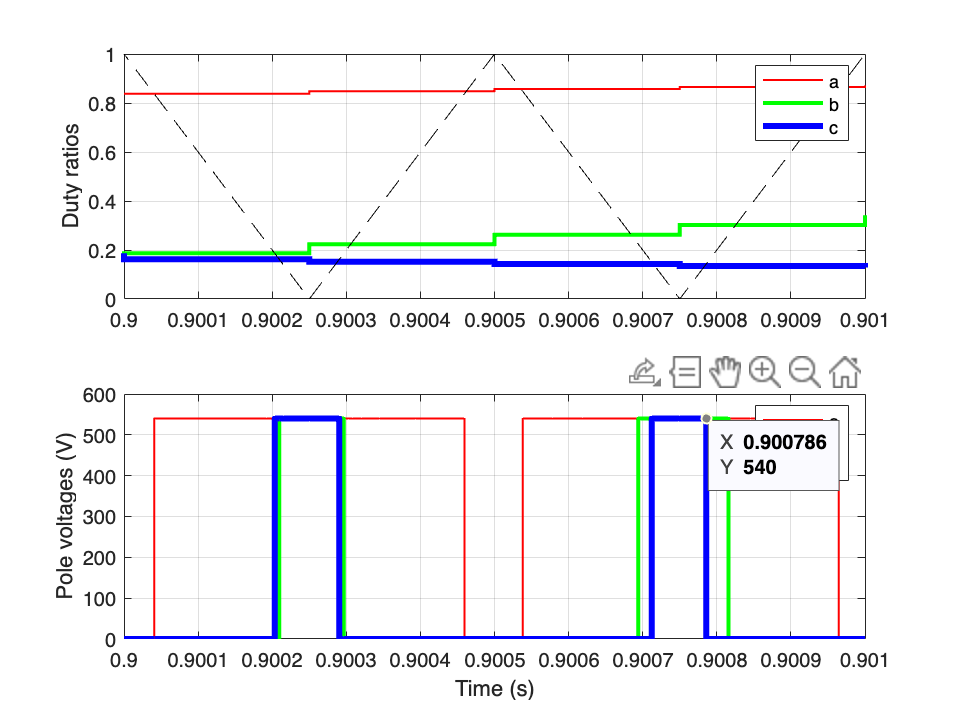

sim("vhz.slx");
fig_vhz;

The lower switching frequency clearly makes the current waveform less ideal and the harmonic content increases. The torque curve remains almost identical because the system function of the induction machine is similar to the low-pass filter. In that application, this behavior is a desired feature that keeps the torque ripple low even if the current has some higher-order harmonic components.